# Example: Fabry-Perot Directivity

This example demonstrates how to model the directional response of Fabry-Perot ultrasound sensors using the `FabryPerotSensor` class. The `FabryPerotSensor` class is a child class of `ElasticMatrix` and is an example of how the `ElasticMatrix` toolbox may be expanded. For more information about the Fabry-Perot ultrasound sensor and modeling process see [1,2].

## Initialize FabryPerotSensor Class

The `FabryPerotSensor` class is initialized with the `Medium` class. For this example an air-backed glass plate sensor is defined.

% Geometry of the Fabry-Perot sensor:
sensor_geometry = Medium('water',Inf, 'glass',175.9e-6, 'air',Inf);

% Initialize the FabryPerotSensor class:
sensor = FabryPerotSensor( sensor_geometry );

## Setting Parameters

`FabryPerotSensor` inherits `ElasticMatrix`, therefore all of the functions available to `ElasticMatrix` are also available to `FabryPerotSensor`. Generally, the Fabry-Perot directivity is calculate over a range of angles and frequencies.

% Set the sensor parameters:
sensor.setAngle( linspace(0, 45, 150) );
sensor.setFrequency( linspace(0.1e6, 50e6, 150) );


Set the interrogating beam spot diameter of the Fabry-Perot sensor:

sensor.setSpotDiameter( 10e-6 );


Set the interrogating laser beam profile of the Fabry-Perot sensor, this can be either '**collimated**' or '**gaussian**':

sensor.setSpotType('gaussian');

Set the locations of the Fabry-Perot mirrors, these are defined as the location of the interfaces, for example between layer index 1 and layer index 2 is interface 1 and between layer index 2 and layer index 3 is interface 2:

interface_1 = 1;
interface_2 = 2;
sensor.setMirrorLocations([interface_1, interface_2])

ans = ==========================================
   FabryPerotSensor  
    Filename:   
  
 
    Properties to set:
 
      property      miniumum    maximum    length      units   
    ____________    ________    _______    ______    __________

    'frequency'     [0.1000]     [50]       150      '[MHz]'   
    'angle'         [0.0100]     [45]       150      '[degree]'
    'phasespeed'    []           []           0      '[m/s]'   
    'wavenumber'    []           []           0      '[1/m]'   

 
    Properties to calculate:
 
            property             calculated
    _________________________    __________

    'partial_wave_amplitudes'      false   
    'x_displacement'               false   
    '

## Calculating Directivity

Use the .`calculateDirectivity` method to calculate the directivity.

% Calculate the directivity:
sensor.calculateDirectivity;

... Calculating directivity ...
... calculating matrix method ... 
... frequency-angle calculation ...
... done ... 
... Finished calculating ...


## Plotting Directivity

There are a number of different ways to plot the modeled directivity. 

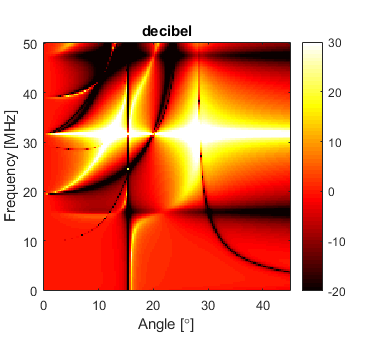

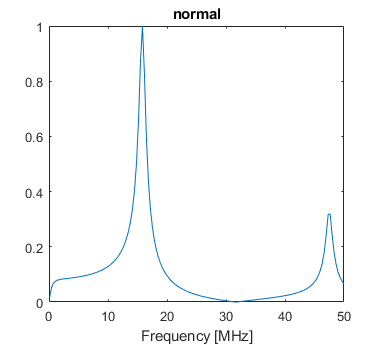

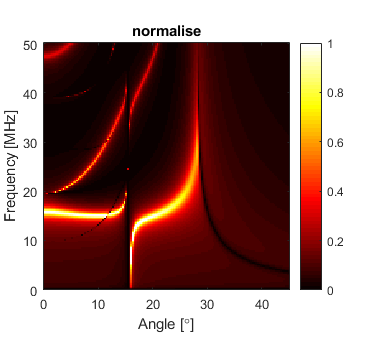

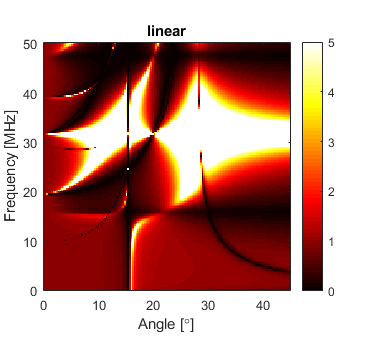

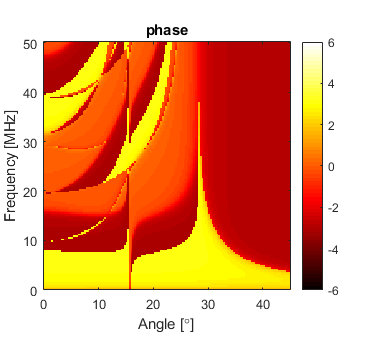

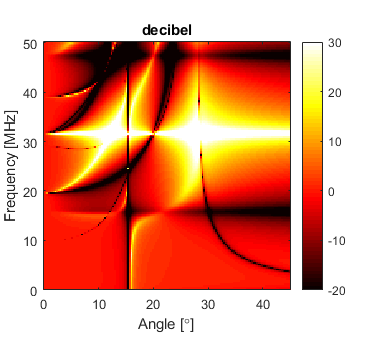

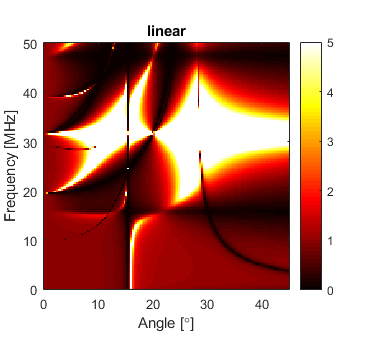

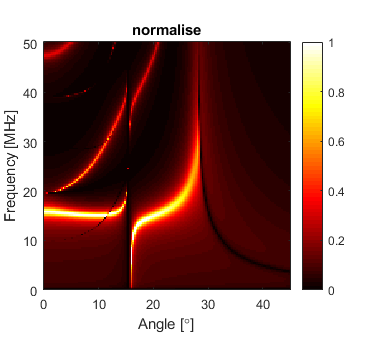

... distributing figures ...


% On the decibel scale:
[figure_handle(1)] = sensor.plotDirectivity('decibel');

% Plot the sensors frequency-response: 
[figure_handle(2)] = sensor.plotDirectivity('normal');

% Plot the directivity normalized to the maximum of the
% frequency-response:
[figure_handle(3)] = sensor.plotDirectivity('normalise');

% Plot the directivity on a linear scale:
[figure_handle(4)] = sensor.plotDirectivity('linear');

% Plot the wrapped phase of the directivity:
[figure_handle(4)] = sensor.plotDirectivity('linear');

% Plot all of the above:
[figure_handle(6:10)] = sensor.plotDirectivity;
 
% Distribute the figures on the screen:
sfg;

## Getting Directivity Data

To process the directional response in a different way the complex directivity can be taken using the .`getDirectivity` method. with these input arguments:

- raw - return complex directivity 

- real - imaginary part of directivity 

- imag - real part of directivity 

- phase - phase of directivity 

- abs - absolute value of the directivity 

- linear - normalized to normal incidence response 

- decibel - plots the previous option on a decibel scale 

- normalise - normalized to maximum value of normal incidence 

- normal - normal incidence response

% For example to get the directivity normalized between 0 and 1:
directivity_normalised = sensor.getDirectivity('normalise');

## About

This file is part of the ElasticMatrix toolbox. Copyright (c) 2019 Danny Ramasawmy.

This file is part of ElasticMatrix. ElasticMatrix is free software: you can redistribute it and/or modify it under the terms of the GNU Lesser General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

ElasticMatrix is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU Lesser General Public License for more details.

You should have received a copy of the GNU Lesser General Public License along with ElasticMatrix. If not, see [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/).